# SVD (Singular Value Decomposition)

## **practice: Application of SVD in field of Image Compression**

## Sample Image Visualization

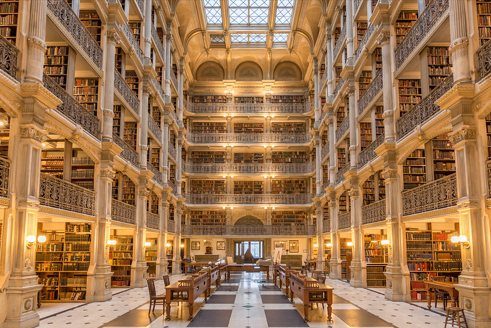

% Read and load input image
input_image = imread('/home/kmw/Downloads/matlabexercise/sample_image.jpg'); % replace 'path_to_your_image.jpg' with your image path
input_image = im2double(input_image); % Convert the image to double precision

## Image Preprocessing

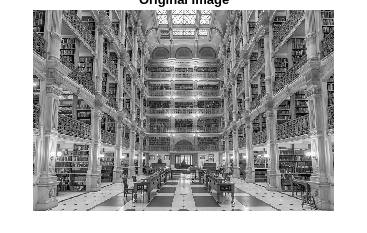

% Convert to grayscale if the image is in color
if size(input_image, 3) == 3
    input_image = rgb2gray(input_image);
end

% Display the original image
figure;
imshow(input_image);
title('Original Image');


% Calculate and print the size of the original image in bytes and MB
original_size_bytes = numel(input_image) * 8; % Convert from double elements to bytes (assuming 8 bits per double)
original_size_mb = original_size_bytes / (1024^2); % Convert from bytes to MB
fprintf('Size of Original Image: %.2f bytes (%.2f MB)\n', original_size_bytes, original_size_mb);

Size of Original Image: 3406936.00 bytes (3.25 MB)


## Solve SVD 

% Perform SVD
[U, S, V] = svd(input_image);

## Visualize Compressed Image

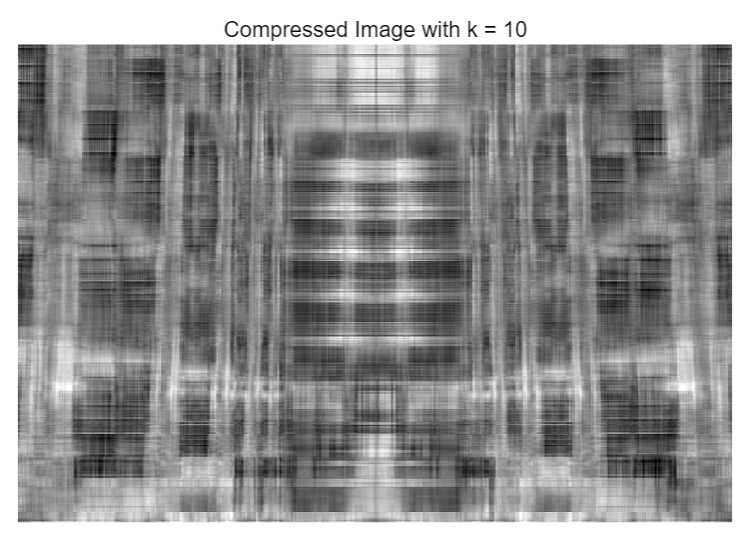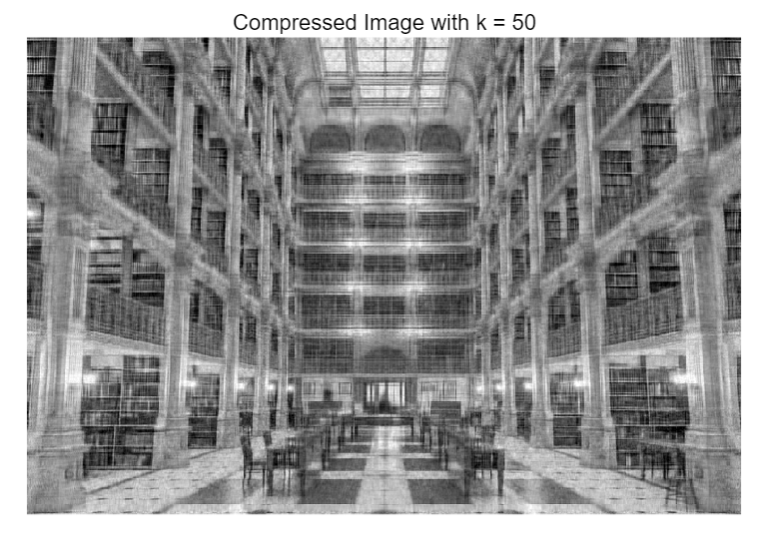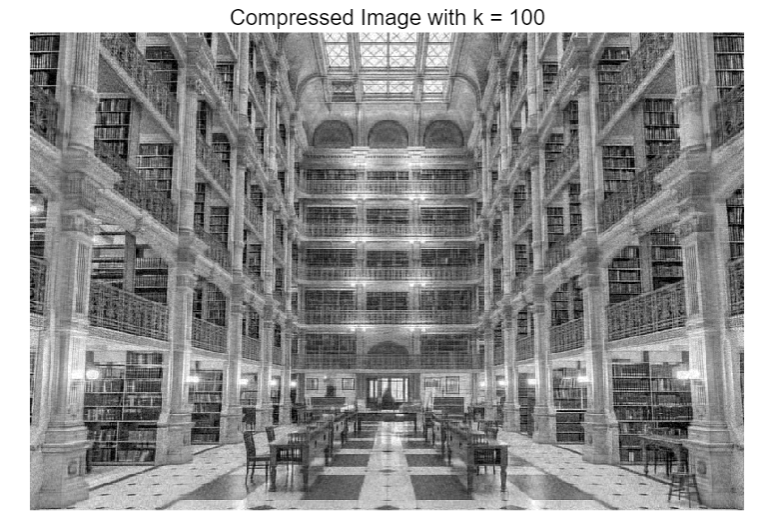

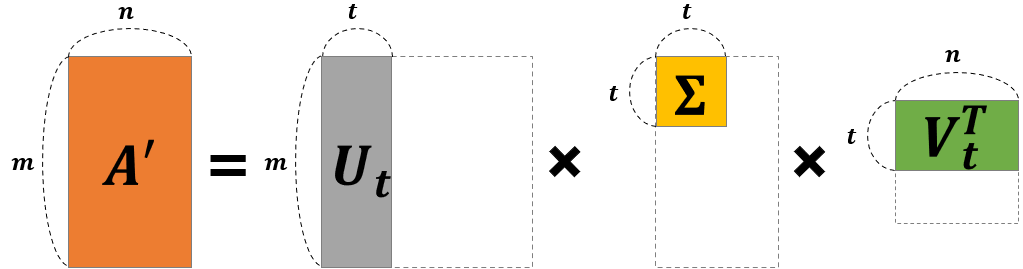

## **Equation of SVD**

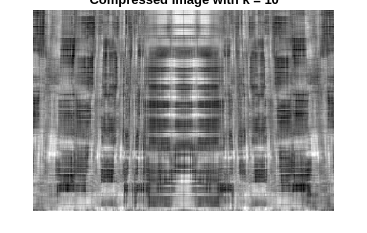

Compression Ratio for k = 10: 0.03


Reconstruction Error for k = 10: 73.61


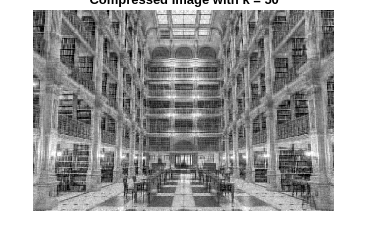

Compression Ratio for k = 50: 0.16


Reconstruction Error for k = 50: 46.63


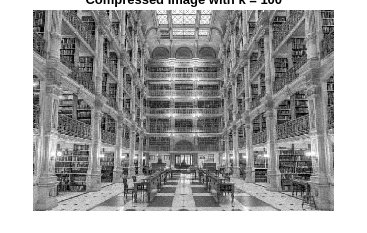

Compression Ratio for k = 100: 0.34


Reconstruction Error for k = 100: 34.63


% Define the number of singular values to keep for compression
k_values = [10, 50, 100]; % You can change these values based on your requirement

for i = 1:length(k_values)
    k = k_values(i);
    
    % Reconstruct the image using the top k singular values using U,S,V matrix
    %%%%%%% TODO %%%%%%%
    compressed_image = U(:, 1:k)*S(1:k, 1:k)*V(:, 1:k)';
    %%%%%%%%%%%%%%%%%%%%
    
    % Display the compressed image
    figure;
    imshow(compressed_image);
    title(['Compressed Image with k = ' num2str(k)]);

    % Calculate the compression ratio using k, U, V
    original_size = numel(input_image);
    %%%%%%% TODO %%%%%%%
    compressed_size = numel(U(:, 1:k)) + numel(S(1:k, 1:k)) + numel(V(:, 1:k)');
    %%%%%%%%%%%%%%%%%%%%
    compression_ratio = compressed_size / original_size;
    fprintf('Compression Ratio for k = %d: %.2f\n', k, compression_ratio);
    
    % Calculate the error between the original and the compressed image
    error = norm(input_image - compressed_image, 'fro');
    fprintf('Reconstruction Error for k = %d: %.2f\n', k, error);
end